# Exercise: Slew Maneuvers with Reaction Wheel Array

A spacecraft shall perform large-angle slew maneuvers around its pitch axis (y-axis) using an array of four reaction wheels with the following alignment matrix:


$$A = \left[\begin{array}{cccc}
	1	&	0	&	0	&	1/\sqrt{3}	\\
	0	&	1	&	0	&	1/\sqrt{3}	\\
	0	&	0	&	1	&	1/\sqrt{3}
\end{array}\right]$$


Every wheel has a maximum angular momentum of $h_{\mathrm{w},\max} = 25\,\mathrm{Nms}$ and a maximum torque of $\dot{h}_{\mathrm{w},\max} = 0.2\,\mathrm{Nm}$.

The spacecraft has a diagonal inertia matrix with $J_x = 1500\,\mathrm{kg m^2}$, $J_y = 1500\,\mathrm{kg m^2}$, and $J_z = 1000\,\mathrm{kg m^2}$. The maximum allowed angular rate is $\omega_{\max} = 1 \degree/\mathrm{s}$.

- What are the performance ratios?

- How long does a rest-to-rest eigenaxis slew around the y-axis take for slew angles of 20°, 50°, and 90°?

- Can the slew times be reduced without changing the number or type of reaction wheels?

clear
close all

addpath('auxFcts/');

## Satellite Properties and Constraints

satAngRateLimit = deg2rad(1);	% [rad/s] max. angular rate: 1 deg/s
rwAngMomMax = 25;	% [Nms] max. angMom per wheel
rwTrqMax = 0.2;	% [Nm] max. torque per wheel

rwaConfMatrix = [1, 0, 0, 1/sqrt(3);
                 0, 1, 0, 1/sqrt(3);
                 0, 0, 1, 1/sqrt(3)];

satMoi = diag([1500,1500, 1000]); % [kg m^2]

slewAngles = [20, 50, 90];	% [rad] 50, 90, or 180 degree slews


## RW AngMom and Torque Envelope

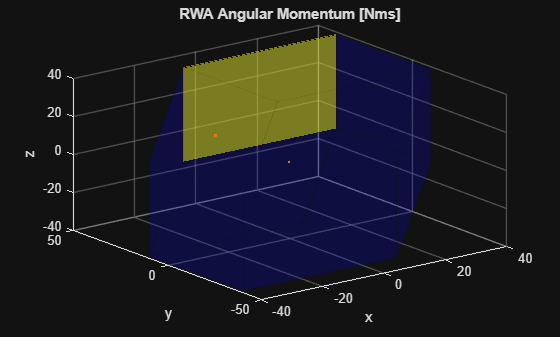

% Compute the zonotope and consider pitch axis (y-axis) as direction of interest
pitchAxis = [0;1;0];

RwaZonoAngMom = rwEnvelope(rwaConfMatrix,rwAngMomMax,pitchAxis);
RwaZonoTrq = rwEnvelope(rwaConfMatrix,rwTrqMax,pitchAxis);

plotZonotope(RwaZonoAngMom);
title('RWA Angular Momentum [Nms]');


% Using the RWA's zonotope's "torque norm" (trqNorm), compute the maximum torque and
% angMom around the pitch axis:
rwaMaxAngMom_y = RwaZonoAngMom.trqNorm;
rwaMaxTrq_y = RwaZonoTrq.trqNorm;

% Compare the maximum rate the RWA can provide with the maximum allowed rate:
rwaMaxPitchRate = rwaMaxAngMom_y / satMoi(2,2); % Maximum angular rate based on maximum angular momentum and relevant inertia
% h = J * omega -> omega = h / J_y
if rwaMaxPitchRate < satAngRateLimit
	maxAngRate = rwaMaxPitchRate;
	fprintf('The reaction wheel array cannot provide the maximum allowed angular rate around y. Thus omega_max = %g deg/s.\n',rwaMaxAngMom_y/satMoi(2,2)*180/pi);
else
	maxAngRate = satAngRateLimit;
	fprintf('The maximum allowed rate is smaller than the one achievable by the reaction wheel array. Thus omega_max = %g deg/s.\n',satAngRateLimit*180/pi);
end

The reaction wheel array cannot provide the maximum allowed angular rate around y. Thus omega_max = 0.000968642 deg/s.


## Performance Ratios

Kc = 0;	% [s] We assume infinite jerk

% Ka_rw is the time the RW needs to accelerate to its maximum angular
% momentum:
Ka_rw = rwAngMomMax / rwTrqMax;	% [s]
% Ka_rw = omega_max/torque_max
% Ka is the time needed for the *spacecraft* to accelerate to the true maximum
% rate computed above:
Ka = maxAngRate * satMoi(2,2) / rwaMaxTrq_y;	% [s] "true" Ka given maxAngRate

% Determine whether the slews are rate- or acceleration-limited:
% First, compute the threshold over which the slew is rate-limited
slewAngThreshold = maxAngRate * (Kc + Ka);	% [rad]
fprintf('Slew angle threshold for rate-limited slews: %g deg.\n',slewAngThreshold*180/pi);

Slew angle threshold for rate-limited slews: 7.74913e-06 deg.


isSlewRateLimited = slewAngles >= slewAngThreshold

isSlewRateLimited = 1×3 logical array
   1   1   1


for ii = 1:1:length(isSlewRateLimited)
	if isSlewRateLimited(ii) == true
		fprintf('Slew #%i is rate-limited.\n',ii);
	else
		fprintf('Slew #%i is acceleration-limited.\n',ii);
	end
end

Slew #1 is rate-limited.
Slew #2 is rate-limited.
Slew #3 is rate-limited.


## Computation of Slew Times

To compute the required slew times, recall the total maneuver time and total slew angles:

### Acceleration-Limited Slews


$$\begin{array}{l}
\Delta t=4\textrm{Kc}+2\;\Delta t_2 =2\Delta t_2 \\
\Delta \varphi =\alpha_{\max } \left(\textrm{Kc}+\Delta t_2 \right)\left(2\textrm{Kc}+\Delta t_2 \right)=\alpha_{\max } \Delta t_2^2 
\end{array}$$


Solving the second line for $\Delta t_2$ and inserting into the first line yields:


$$\Delta t=2\sqrt{\;\frac{\Delta \varphi \;}{\alpha_{\max } }}$$


### Rate-Limited Slews


$$\begin{array}{l}
\Delta t=2\textrm{Kc}+2\textrm{Ka}+\Delta \;t_3 \\
\Delta \varphi =\omega_{\max } \;\left(\textrm{Kc}+\textrm{Ka}+\Delta \;t_3 \right)
\end{array}$$


Solving the second line for $\Delta t_3$ and inserting into the first line yields:


$$\Delta t=\frac{\Delta \;\varphi \;}{\omega_{\max } }+\textrm{Kc}+\textrm{Ka}$$


### Slew 1: 20°


slewTimes(1) =  deg2rad(20)/maxAngRate+0+Ka; % [s]
disp(slewTimes(1))

   2.0647e+04



### Slew 2: 50°

slewTimes(2) = deg2rad(50)/maxAngRate+0+Ka; % [s]
disp(slewTimes(2))

   5.1619e+04



### Slew 3: 90°

slewTimes(3) = deg2rad(90)/maxAngRate+0+Ka; % [s]
disp(slewTimes(3))

   9.2914e+04





slewTimes = zeros(1, length(slewAngles));

for i = 1:length(slewAngles)
    angleRad = deg2rad(slewAngles(i));
    if isSlewRateLimited(i)
        % Rate-limited Fall
        slewTimes(i) = angleRad / maxAngRate + Kc + Ka;
        disp(slewTimes(i))
    else
        % Acceleration-limited Fall
        alpha_max = rwaMaxTrq_y / satMoi(2,2);
        slewTimes(i) = sqrt(2 * angleRad / alpha_max);
        disp(slewTimes(i))
    end
end

   2.0647e+04

   5.1619e+04

   9.2914e+04

